Mr Zapp

clear all

rfzapp = readtable('rfZapp.csv')

rfzapp = 65×2 table
       date         rf  
    __________    ______

    01/06/2019    -0.668
    01/07/2019    -0.703
    01/08/2019     -0.85
    01/09/2019    -0.687
    01/10/2019    -0.638
    01/11/2019    -0.617
    01/12/2019    -0.635
    01/01/2020    -0.602
    01/02/2020    -0.712
    01/03/2020     -0.65
    01/04/2020    -0.547
    01/05/2020    -0.578
    01/06/2020    -0.547
    01/07/2020    -0.574
    01/08/2020    -0.553
    01/09/2020    -0.587


TT=table2timetable(rfzapp);
rf_z=(TT.rf/100)/12;
avrg_rf_z=mean(rf_z)

avrg_rf_z = 7.6023e-04

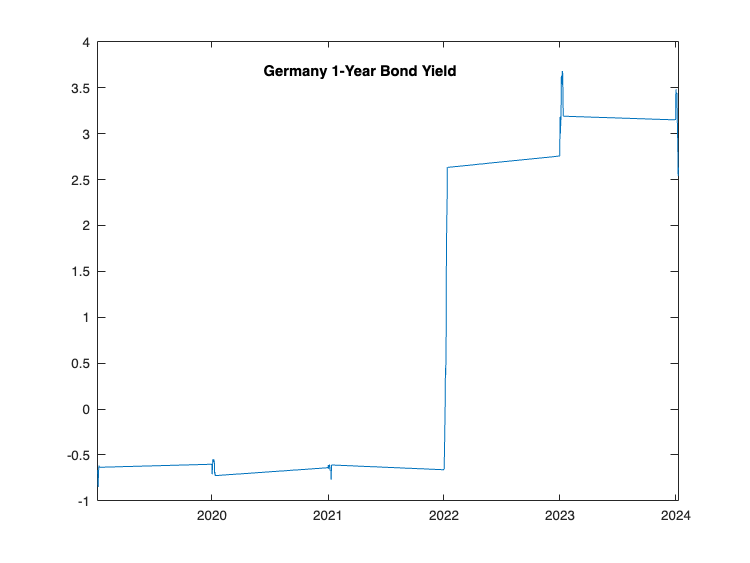

figure, plot(TT.date, TT.rf)
title('Germany 1-Year Bond Yield')

warning ('off')

sxr0 = readtable('SXR0.csv')

sxr0 = 66×1 table
    SXR0 
    _____

    5.755
    5.954
    6.049
    6.088
    6.166
    6.163
    6.251
    6.285
     6.41
    5.836
    5.389
    5.706
    5.808
    5.785
    5.917
    6.053


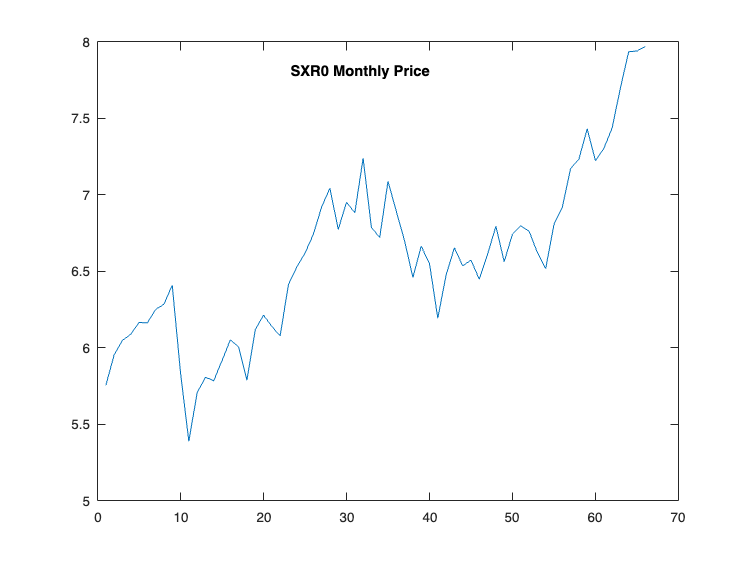

sxr0=sxr0.SXR0;
figure, plot(sxr0)
title('SXR0 Monthly Price')

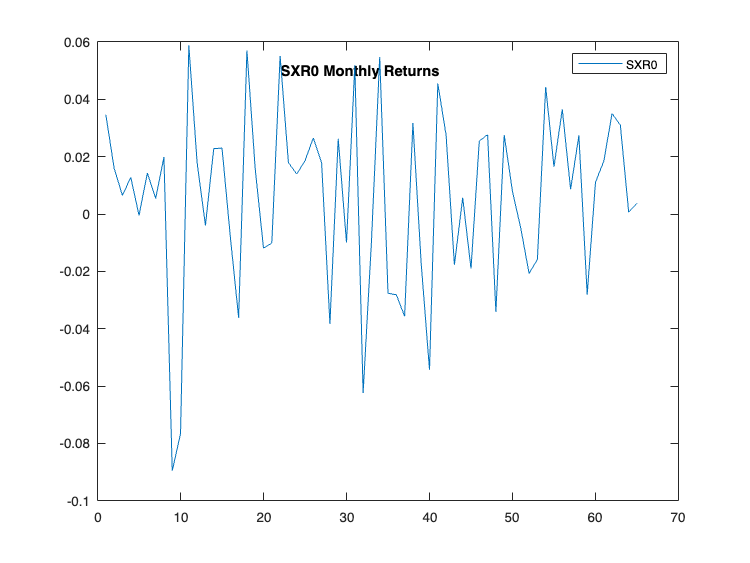

sxr0_ret=price2ret(sxr0,Method="periodic");
figure, plot(sxr0_ret)
title('SXR0 Monthly Returns')
legend('SXR0');

er_sxr0=sxr0_ret-rf_z;
avrg_er_sxr0=mean(er_sxr0)

avrg_er_sxr0 = 0.0048

std_er_sxr0=std(er_sxr0)

std_er_sxr0 = 0.0315

gcbond = readtable('36B7.csv')

gcbond = 66×1 table
    x36B7
    _____

    5.04 
    5.15 
    5.18 
    5.28 
    5.19 
     5.2 
     5.2 
     5.2 
    5.29 
    5.29 
    4.92 
    5.13 
    5.17 
    5.28 
    5.38 
    5.33 


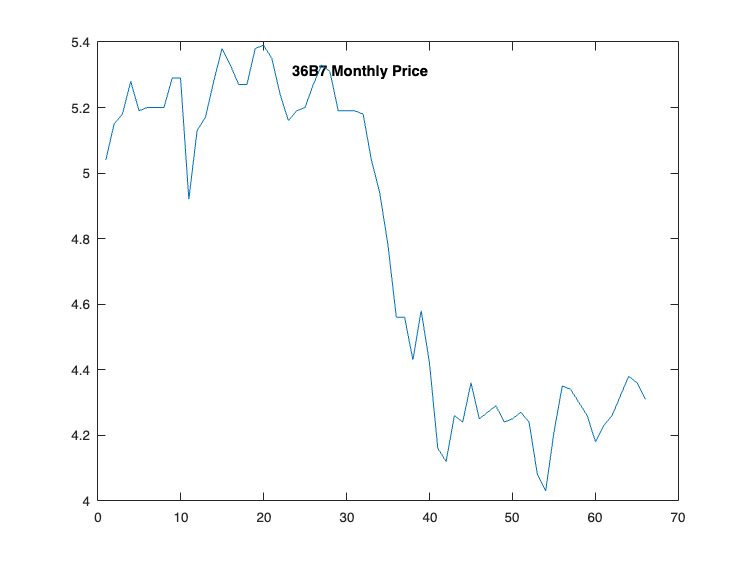

gcbond=gcbond.x36B7;
figure, plot(gcbond)
title('36B7 Monthly Price')

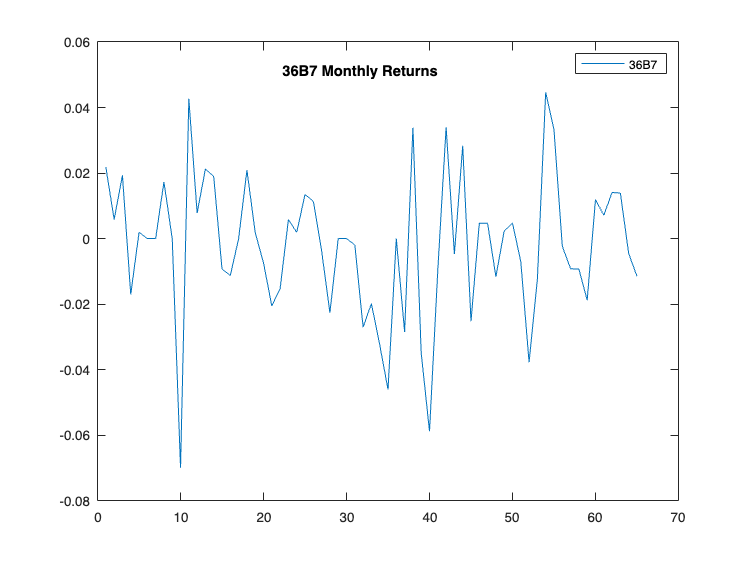

gcbond_ret=price2ret(gcbond,Method="periodic");
figure, plot(gcbond_ret)
title('36B7 Monthly Returns')
legend('36B7');

er_gcbond=gcbond_ret-rf_z;
avrg_er_gcbond=mean(er_gcbond)

avrg_er_gcbond = -0.0029

std_er_gcbond=std(er_gcbond)

std_er_gcbond = 0.0219


sreeex = readtable('SREEEX.csv')

sreeex = 66×1 table
    SKREEEX
    _______

     17.91 
     17.28 
     17.29 
     17.73 
     18.57 
     19.02 
     19.37 
     19.89 
     20.17 
     18.78 
     14.75 
     15.37 
     15.66 
     15.86 
     15.92 
     16.31 


sreeex=sreeex.SKREEEX;
figure, plot(sreeex)
title('SREEEX Monthly Price')
sreeex_ret=price2ret(sreeex,Method="periodic");
figure, plot(sreeex_ret)
title('SREEEX Monthly Returns')
legend('SREEEX');
er_sreeex=sreeex_ret-rf_z;
avrg_er_sreeex=mean(er_sreeex)

avrg_er_sreeex = -9.6369e-04

std_er_sreeex=std(er_sreeex)

std_er_sreeex = 0.0689


m = [ avrg_er_sxr0; avrg_er_gcbond; avrg_er_sreeex ];

stds= [std_er_sxr0 std_er_gcbond std_er_sreeex];
corr_sxr0_gcbond=corrcoef(er_sxr0,er_gcbond)

corr_sxr0_gcbond =     1.0000    0.5903
    0.5903    1.0000


corr_sxr0_gcbond=corr_sxr0_gcbond(1,2)

corr_sxr0_gcbond = 0.5903

corr_sxr0_sreeex=corrcoef(er_sxr0,er_sreeex)

corr_sxr0_sreeex =     1.0000    0.6744
    0.6744    1.0000


corr_sxr0_sreeex=corr_sxr0_sreeex(1,2)

corr_sxr0_sreeex = 0.6744

corr_gcbond_sreeex=corrcoef(er_gcbond,er_sreeex)

corr_gcbond_sreeex =     1.0000    0.7133
    0.7133    1.0000


corr_gcbond_sreeex=corr_gcbond_sreeex(1,2)

corr_gcbond_sreeex = 0.7133

corrs = [1 corr_sxr0_gcbond corr_sxr0_sreeex; corr_sxr0_gcbond 1 corr_gcbond_sreeex; corr_sxr0_sreeex corr_gcbond_sreeex 1]

corrs =     1.0000    0.5903    0.6744
    0.5903    1.0000    0.7133
    0.6744    0.7133    1.0000


c=corr2cov(stds,corrs)

c =     0.0010    0.0004    0.0015
    0.0004    0.0005    0.0011
    0.0015    0.0011    0.0047



ETFs = {'SXR0','36B7','SREEEX'};

p = Portfolio('AssetList', ETFs);
p = Portfolio(p, 'LowerBound', -ones(size(m))); % Allow short positions
p = Portfolio(p, 'LowerBudget', 1, 'UpperBudget', 1);
p = Portfolio(p, 'AssetMean', m, 'AssetCovar', c);
plotFrontier(p);
pwgt = estimateFrontier(p, 20) % Choose Three efficient portfolios. Each column contains portfolio weights

pwgt =     0.2762    0.4127    0.5493    0.6858    0.8223    0.9588    1.0953    1.2318    1.3684    1.5049    1.6414    1.7779    1.9144    2.0509    2.1875    2.3240    2.4639    2.6426    2.8213    3.0000
    0.9594    0.8363    0.7132    0.5901    0.4671    0.3440    0.2209    0.0978   -0.0253   -0.1483   -0.2714   -0.3945   -0.5176   -0.6407   -0.7638   -0.8868   -1.0000   -1.0000   -1.0000   -1.0000
   -0.2356   -0.2490   -0.2625   -0.2759   -0.2894   -0.3028   -0.3162   -0.3297   -0.3431   -0.3565   -0.3700   -0.3834   -0.3968   -0.4103   -0.4237   -0.4371   -0.4639   -0.6426   -0.8213   -1.0000



[stdF, retF] = estimatePortMoments(p, pwgt)

stdF =     0.0179
    0.0182
    0.0191
    0.0205
    0.0223
    0.0245
    0.0268
    0.0294
    0.0321
    0.0349


retF =    -0.0013
   -0.0002
    0.0008
    0.0018
    0.0028
    0.0038
    0.0049
    0.0059
    0.0069
    0.0079



hold on
plot(stdF,retF,'*r');

hold off 

pwgtl = estimateFrontierLimits(p)

pwgtl =     0.2762    3.0000
    0.9594   -1.0000
   -0.2356   -1.0000



SharpeRM= retF ./stdF

SharpeRM =    -0.0707
   -0.0133
    0.0409
    0.0879
    0.1266
    0.1573
    0.1815
    0.2004
    0.2153
    0.2272



bar(SharpeRM)

weights = estimateMaxSharpeRatio(p)

weights =     2.5340
   -1.0000
   -0.5340



[riskM, retM] = estimatePortMoments(p, weights)

riskM = 0.0577

retM = 0.0155


SharpeR= retM/riskM

SharpeR = 0.2688

Ms Yanny

rfyanny = readtable('rfYanny.csv')

rfyanny = 152×2 table
       Date       rfYanny
    __________    _______

    03/01/2012      1.04 
    04/01/2012     0.813 
    05/01/2012     0.657 
    06/01/2012     0.716 
    07/01/2012     0.586 
    08/01/2012     0.588 
    09/01/2012     0.625 
    10/01/2012     0.721 
    11/01/2012     0.619 
    12/01/2012     0.725 
    01/01/2013      0.88 
    02/01/2013     0.766 
    03/01/2013     0.769 
    04/01/2013     0.678 
    05/01/2013     1.024 
    06/01/2013     1.396 


TT=table2timetable(rfyanny);
rf_y=(TT.rfYanny/100)/12;
avrg_rf_y=mean(rf_y)

avrg_rf_y = 0.0016

figure, plot(TT.Date, TT.rfYanny)
title('US 5-Year Bond Yield')
warning ('off')

qqq = readtable('qqq.csv')

qqq = 153×2 table
    Var1    Var2
    ____    ____

     64      11 
     67      24 
     66      45 
     61      77 
     63      86 
     64       5 
     67      84 
     68      25 
     64      65 
     65      49 
     64      83 
     66      56 
     66      79 
     68      65 
     70      39 
     72      91 


qqq=qqq.qqq;

Error using  .  (line 229)
Unrecognized table variable name 'qqq'.

figure, plot(qqq)
title('QQQ Monthly Price')
qqq_ret=price2ret(qqq,Method="periodic");
figure, plot(qqq_ret)
title('QQQ Monthly Returns')
legend('QQQ');
er_qqq=qqq_ret-rf_y;
avrg_er_qqq=mean(er_qqq)
std_er_qqq=std(er_qqq)

djcbp = readtable('djcbp.csv')
djcbp=djcbp.djcbp;
figure, plot(djcbp)
title('DJCBP Monthly Price')
djcbp_ret=price2ret(djcbp,Method="periodic");
figure, plot(djcbp_ret)
title('DJCBP Monthly Returns')
legend('DJCBP');
er_djcbp=djcbp_ret-rf_y;
avrg_er_djcbp=mean(er_djcbp)
std_er_djcbp=std(er_djcbp)

urth = readtable('urth.csv')
urth=urth.urth;
figure, plot(urth)
title('URTH Monthly Price')
urth_ret=price2ret(urth,Method="periodic");
figure, plot(urth_ret)
title('URTH Monthly Returns')
legend('URTH');
er_urth=urth_ret-rf_y;
avrg_er_urth=mean(er_urth)
std_er_urth=std(er_urth)

gld = readtable('gld.csv')
gld=gld.gld;
figure, plot(gld)
title('GLD Monthly Price')
gld_ret=price2ret(gld,Method="periodic");
figure, plot(gld_ret)
title('GLD Monthly Returns')
legend('GLD');
er_gld=gld_ret-rf_y;
avrg_er_gld=mean(er_gld)
std_er_gld=std(er_gld)

ma = [ avrg_er_qqq; avrg_er_djcbp; avrg_er_urth; avrg_er_gld ];

stdsa= [std_er_qqq std_er_djcbp std_er_urth std_er_gld];

corr_qqq_djcbp=corrcoef(er_qqq,er_djcbp)
corr_qqq_djcbp=corr_qqq_djcbp(1,2)

corr_qqq_urth=corrcoef(er_qqq,er_urth)
corr_qqq_urth=corr_qqq_urth(1,2)

corr_qqq_gld=corrcoef(er_qqq,er_gld)
corr_qqq_gld=corr_qqq_gld(1,2)

corr_djcbp_urth=corrcoef(er_djcbp,er_urth)
corr_djcbp_urth=corr_djcbp_urth(1,2)

corr_djcbp_gld=corrcoef(er_djcbp,er_gld)
corr_djcbp_gld=corr_djcbp_gld(1,2)

corr_urth_gld=corrcoef(er_urth,er_gld)
corr_urth_gld=corr_urth_gld(1,2)

corrsa = [1 corr_qqq_djcbp corr_qqq_urth corr_qqq_gld; corr_qqq_djcbp 1 corr_djcbp_urth corr_djcbp_gld; corr_qqq_urth corr_djcbp_urth 1 corr_urth_gld; corr_qqq_gld corr_djcbp_gld corr_urth_gld 1]
ca=corr2cov(stdsa,corrsa)

ETFsa = {'QQQ','DJCBP','URTH','GLD'};

pa = Portfolio('AssetList', ETFsa);
pa = Portfolio(pa, 'lowerbound', -1); % Allow short positions
pa = Portfolio(pa, 'LowerBudget', 1, 'UpperBudget', 1);
pa = Portfolio(pa, 'AssetMean', ma, 'AssetCovar', ca);
plotFrontier(pa);
pwgta = estimateFrontier(pa, 20) % Choose Three efficient portfolios. Each column contains portfolio weights

[stdFa, retFa] = estimatePortMoments(pa, pwgta)

hold on
plot(stdFa,retFa,'*r');

hold off 

pwgtla = estimateFrontierLimits(pa)

SharpeRMa= retFa ./stdFa

bar(SharpeRMa)

weightsa = estimateMaxSharpeRatio(pa)

[riskMa, retMa] = estimatePortMoments(pa, weightsa)

SharpeRa= retMa/riskMa